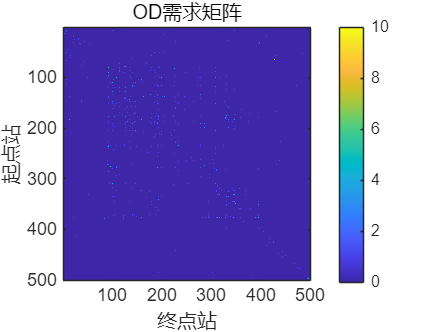

clc,clear
data = readtable("bike_data.xlsx");
stations = unique([data.start_station_id; data.end_station_id]);

% 3. 构建OD矩阵
% 行表示起点, 列表示终点, 矩阵元素表示从起点到终点的OD点对, 可以用颜色编码OD点对数量.为了处理大量的数据,
% 重新排序和聚合技术也被应用于 OD 矩阵, 以提高信息表达和可视化效率。
n = length(stations);
OD = zeros(n, n);
station_map = containers.Map(stations, 1:n);

for i = 1:height(data)
    s = station_map(data.start_station_id(i));
    e = station_map(data.end_station_id(i));
    OD(s, e) = OD(s, e) + 1;
end

% 4. 可视化
imagesc(OD); colorbar;
title('OD需求矩阵');
xlabel('终点站'); ylabel('起点站');


% 入流量：所有以该站为终点的次数
inflow = sum(OD, 1)';

% 出流量：所有以该站为起点的次数
outflow = sum(OD, 2);

% 净需求量 = inflow - outflow
delta = inflow - outflow;

% 决策变量 x(i): 站点 i 应增加/减少的单车数
% 最小化：∑ |x(i)|  使得 delta(i) + x(i) ≈ 0

% 使用二次规划更平滑（或 L1 规划）

H = eye(n);                  % 最小化 x'x，防止极端调度
f = delta;                   % 等价于最小化 (x + delta)'(x + delta) 通过 f = delta 来让误差最小化

% 没有 Aeq / beq
Aeq = [];
beq = [];
lb = -inf(n,1);  % 或者你设定的调度下限
ub = inf(n,1);   % 或者你设定的调度上限
x_opt = quadprog(H, f, [], [], Aeq, beq, lb, ub);


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


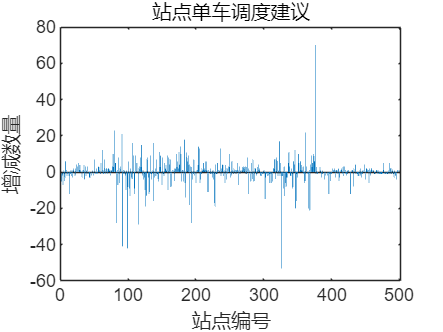


% 结果可视化
bar(x_opt); 
title("站点单车调度建议"); 
xlabel("站点编号"); 
ylabel("增减数量");

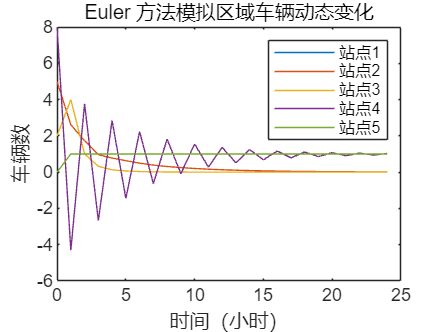


% 生成迁移概率矩阵 T
% 构建迁移概率矩阵 T（按行归一化）
T = OD ./ sum(OD, 2);
T(isnan(T)) = 0; % 避免除零

% 定义动力学系统（ODE）
% 封装车辆数变化模型
function dxdt = bike_ode(t, x, T, u)
    inflow = T' * x;
    outflow = sum(T, 2) .* x;
    dxdt = inflow - outflow + u;  % u: 调度影响
end

% 使用 Euler 方法模拟 24 小时运行
% 时间设置
h = 1;               % 时间步长：1小时
T_total = 24;        % 模拟 24 小时
steps = T_total / h;

% 初始化
x_euler = zeros(n, steps+1);
x_euler(:,1) = inflow; % 初始状态可设为 inflow、outflow 或 x_opt 等

% 假设调度为固定策略：使用静态优化值
u = x_opt;

% 动态模拟
for k = 1:steps
    dx = bike_ode(k, x_euler(:,k), T, u);
    x_euler(:,k+1) = x_euler(:,k) + h * dx;
end

% 可视化前几个站点
figure;
plot(0:h:T_total, x_euler(1:5,:)');
title('Euler 方法模拟区域车辆动态变化');
xlabel('时间（小时）'); ylabel('车辆数');
legend("站点1", "站点2", "站点3", "站点4", "站点5");

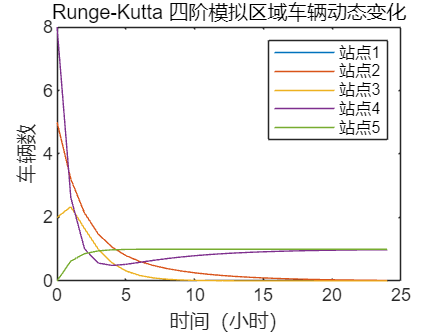


% 替换为 Runge-Kutta 四阶
x_rk = zeros(n, steps+1);
x_rk(:,1) = inflow;

for k = 1:steps
    k1 = bike_ode(k, x_rk(:,k), T, u);
    k2 = bike_ode(k + h/2, x_rk(:,k) + h/2*k1, T, u);
    k3 = bike_ode(k + h/2, x_rk(:,k) + h/2*k2, T, u);
    k4 = bike_ode(k + h, x_rk(:,k) + h*k3, T, u);
    x_rk(:,k+1) = x_rk(:,k) + h/6 * (k1 + 2*k2 + 2*k3 + k4);
end

% 可视化
figure;
plot(0:h:T_total, x_rk(1:5,:)');
title('Runge-Kutta 四阶模拟区域车辆动态变化');
xlabel('时间（小时）'); ylabel('车辆数');
legend("站点1", "站点2", "站点3", "站点4", "站点5");

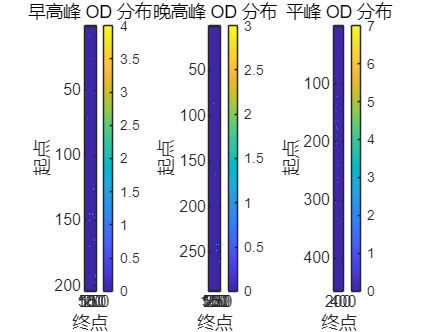


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. 转换时间为 datetime 类型
data.started_at = datetime(data.started_at, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
data.ended_at = datetime(data.ended_at, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

% 3. 定义不同时段
morning_peak = (hour(data.started_at) >= 7 & hour(data.started_at) < 9);
evening_peak = (hour(data.started_at) >= 17 & hour(data.started_at) < 19);
off_peak = ~(morning_peak | evening_peak);

% 4. 提取不同时段数据
data_morning = data(morning_peak, :);
data_evening = data(evening_peak, :);
data_off = data(off_peak, :);

% ----------------- 不同时段 OD 差异热力图对比 ----------------- %
% 分别构建每个时间段的 OD 矩阵
OD_morning = build_od(data_morning);
OD_evening = build_od(data_evening);
OD_off = build_od(data_off);

% 绘图比较
figure;
subplot(1,3,1); imagesc(OD_morning); colorbar; title('早高峰 OD 分布');
xlabel('终点'); ylabel('起点');

subplot(1,3,2); imagesc(OD_evening); colorbar; title('晚高峰 OD 分布');
xlabel('终点'); ylabel('起点');

subplot(1,3,3); imagesc(OD_off); colorbar; title('平峰 OD 分布');
xlabel('终点'); ylabel('起点');

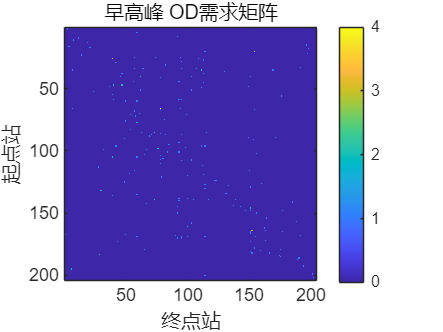


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


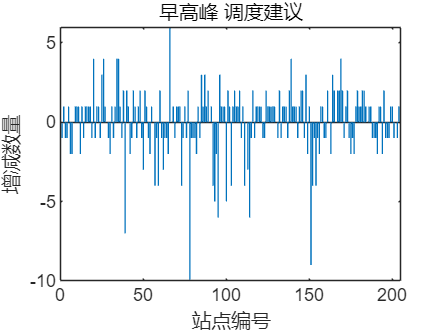

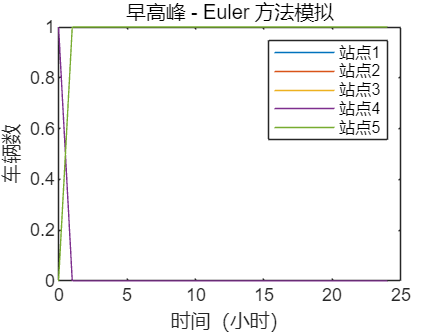

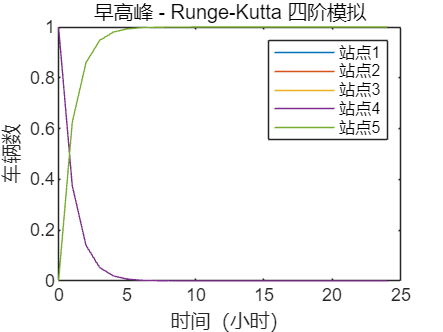


% 计算调度优化结果并保存
schedule_result = table((1:n)', x_opt, 'VariableNames', {'StationID', 'BikeAdjustment'});
writetable(schedule_result, 'bike_schedule.csv');

% 保存 Euler 模拟结果
euler_result = array2table(x_euler', 'VariableNames', strcat('Station', string(1:n)));
euler_result.Time = (0:h:T_total)';  % 添加时间列
writetable(euler_result, 'bike_dynamic_euler.csv');

% 保存 Runge-Kutta 模拟结果
rk_result = array2table(x_rk', 'VariableNames', strcat('Station', string(1:n)));
rk_result.Time = (0:h:T_total)';  % 添加时间列
writetable(rk_result, 'bike_dynamic_rk.csv');


% ----------------- 不同时段车辆动态流量差异对比 ----------------- %

[~, x_morning] = simulate_bike_flow(data_morning, '早高峰');

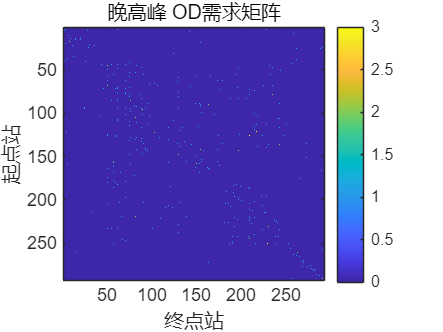


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


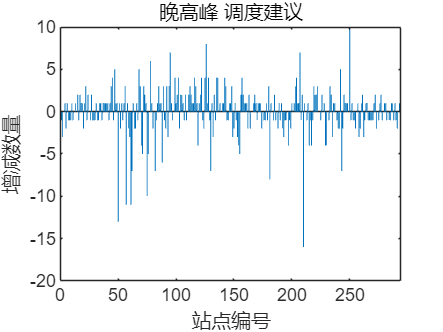

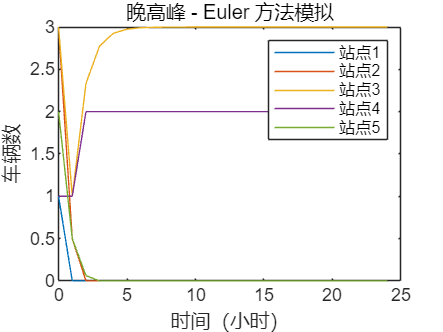

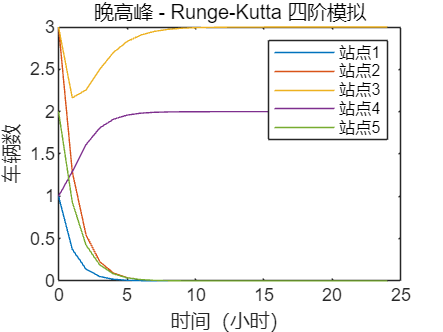

[~, x_evening] = simulate_bike_flow(data_evening, '晚高峰');

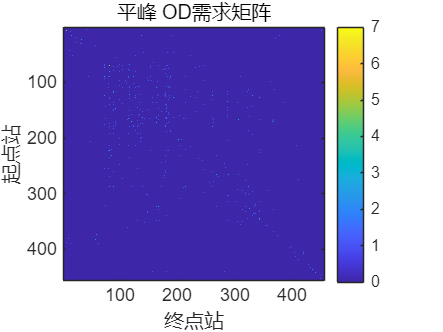


找到满足约束的最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值的范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


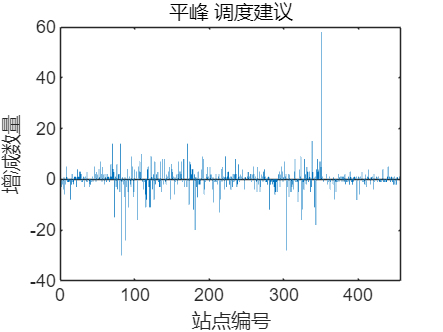

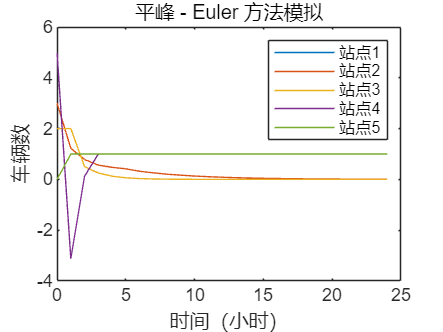

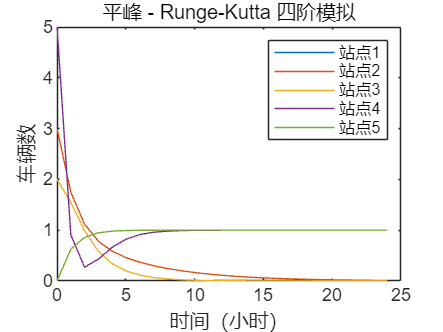

[~, x_off]     = simulate_bike_flow(data_off, '平峰');


% ========= 函数定义 ========= %
function [T, x_rk] = simulate_bike_flow(data, label)
    stations = unique([data.start_station_id; data.end_station_id]);
    n = length(stations);
    OD = zeros(n, n);
    station_map = containers.Map(stations, 1:n);

    for i = 1:height(data)
        s = station_map(data.start_station_id(i));
        e = station_map(data.end_station_id(i));
        OD(s, e) = OD(s, e) + 1;
    end

    % 可视化OD
    figure;
    imagesc(OD); colorbar;
    title([label ' OD需求矩阵']);
    xlabel('终点站'); ylabel('起点站');

    inflow = sum(OD, 1)';
    outflow = sum(OD, 2);
    delta = inflow - outflow;

    % 调度优化
    H = eye(n);
    f = delta;
    Aeq = []; beq = [];
    lb = -inf(n,1); ub = inf(n,1);
    x_opt = quadprog(H, f, [], [], Aeq, beq, lb, ub);

    figure;
    bar(x_opt);
    title([label ' 调度建议']);
    xlabel("站点编号"); ylabel("增减数量");

    % 迁移概率矩阵
    T = OD ./ sum(OD, 2);
    T(isnan(T)) = 0;

    % 动态系统定义
    function dxdt = bike_ode(~, x, T, u)
        inflow = T' * x;
        outflow = sum(T, 2) .* x;
        dxdt = inflow - outflow + u;
    end

    % 时间设置
    h = 1; T_total = 24; steps = T_total / h;
    x0 = inflow; % 可替换为 outflow 或 x_opt

    % Euler 模拟
    x_euler = zeros(n, steps+1);
    x_euler(:,1) = x0;
    u = x_opt;

    for k = 1:steps
        dx = bike_ode(k, x_euler(:,k), T, u);
        x_euler(:,k+1) = x_euler(:,k) + h * dx;
    end

    % RK4 模拟
    x_rk = zeros(n, steps+1);
    x_rk(:,1) = x0;
    for k = 1:steps
        k1 = bike_ode(k, x_rk(:,k), T, u);
        k2 = bike_ode(k + h/2, x_rk(:,k) + h/2*k1, T, u);
        k3 = bike_ode(k + h/2, x_rk(:,k) + h/2*k2, T, u);
        k4 = bike_ode(k + h, x_rk(:,k) + h*k3, T, u);
        x_rk(:,k+1) = x_rk(:,k) + h/6 * (k1 + 2*k2 + 2*k3 + k4);
    end

    % 可视化
    figure;
    plot(0:h:T_total, x_euler(1:5,:)');
    title([label ' - Euler 方法模拟']);
    xlabel('时间（小时）'); ylabel('车辆数');
    legend("站点1", "站点2", "站点3", "站点4", "站点5");

    figure;
    plot(0:h:T_total, x_rk(1:5,:)');
    title([label ' - Runge-Kutta 四阶模拟']);
    xlabel('时间（小时）'); ylabel('车辆数');
    legend("站点1", "站点2", "站点3", "站点4", "站点5");
    T = T;  % 可返回迁移矩阵供后续比较使用
end

function OD = build_od(data)
    stations = unique([data.start_station_id; data.end_station_id]);
    n = length(stations);
    OD = zeros(n, n);
    station_map = containers.Map(stations, 1:n);
    for i = 1:height(data)
        s = station_map(data.start_station_id(i));
        e = station_map(data.end_station_id(i));
        OD(s, e) = OD(s, e) + 1;
    end
end
